% global FixPeakChannel peak_point_define
% FixPeakChannel=1;
% peak_point_define=42;
cd('/Volumes/PcSSDA/1626/20220329_1626_SW_004')
ExperimentName='20220329_1626_SW_004'; % Give a specific name to this experiment or this analysis
FirstAcq=10; % What's the acquisition number of the first offical recording
number_of_acq = 17; % How many chunks of recordings are there?
Dark_hours=[10 11 12 13 14 15 16 17 18 19 20 21 22]

Dark_hours =     10    11    12    13    14    15    16    17    18    19    20    21    22


darktime_calc = 0; % 0 or 1, determining different method to calculate dark time

analysis_name=[ExperimentName,'_analysis_'];
timebin=1;
ch=1;
FLPfiles='continuous aquistion data_'; 


load('FLP_analysis_0426.mat')

figure
plot(time_z_all_darkonly)

time_max = max(time_z_all_darkonly)

time_max =      4.319923900000000e+04


length(time_z_all_darkonly)

ans =        41907


min(time_z_all_darkonly)

ans =    0.360000000000582


% time_pooled = (2:4:(ceil(time_max/4)*4)) + 12*900;
time_pooled = (0:1:(length(time_pooled)-1)) + 10800;
circadian_time = NaN(ceil(time_max/4),1);
% time_pooled = zeros(ceil(time_max/4),1);
tau_pooled = NaN(ceil(time_max/4),1);
states_pooled = NaN(ceil(time_max/4),1);

helper = 1;

for i = 1:ceil(time_max/4)
    index = find(time_z_all_darkonly > (i-1)*4 & time_z_all_darkonly <= i*4);
    circadian_time(i) = time_pooled(i);

    if isempty(index) == 0
        weighted_sum = sum(tau_empTrunc_all_darkonly(index).*intensity_all_darkonly (index));
        tau_pooled(i) = weighted_sum/sum(intensity_all_darkonly (index));
        states_pooled(i) = states_for_time_all_dark(index(1));
        helper = helper*0;
    elseif helper ==0
        tau_pooled(i) = tau_pooled(i-1);
        states_pooled(i) = states_pooled(i-1);
%         time_pooled(i) = NaN;

    end

end

size(tau_pooled)

ans =        10800           1


size(states_pooled)

ans =        10800           1


size(circadian_time)

ans =        10800           1


sum(isnan(tau_pooled))

ans =      0


sum(isnan(states_pooled))

ans =      0


sum(isnan(circadian_time))

ans =      0


Temperature_path='/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/'

Temperature_path = '/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/'

cd(Temperature_path)
rawData_all = ([Temperature_path,'rawData_all_0920.mat'])

rawData_all = '/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/rawData_all_0920.mat'

OptResults_all =([Temperature_path,'OptResults_all_0922.mat'])

OptResults_all = '/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/OptResults_all_0922.mat'

load(OptResults_all)
initial_temperature = 4.1365; % negative value produces an estimated initial temperature
minutesToInitialT = 5;
SF=4;

% Use the median parameter values from Table 1:
p.sizePWP = OptimizedParameters.sizePWP;              % window size (in hours) of the prior wake prevelance (PWP)
p.shiftPWP = OptimizedParameters.shiftPWP;          % window shift (in hours) of the prior wake prevelance (PWP)
p.lowerAsymptote = OptimizedParameters.lowerAsymptote;   % Lower asymptote value (in C)
p.upperAsymptote =  OptimizedParameters.upperAsymptote;  % Upper Asymptote value (in C)
p.wakeTimeConstant = OptimizedParameters.wakeTimeConstant;  % Time constant of wake and REM states
p.nremTimeConstant = OptimizedParameters.nremTimeConstant;  % Time constant of NREM sleep
p.scalePWP = OptimizedParameters.scalePWP;          % The multiplier of PWP values
p.circadianAmplitude = OptimizedParameters.circadianAmplitude;% The multiplier of the circadian values
p.circadianPhase = OptimizedParameters.circadianPhase;   % Phase shift of circadian process (in hours)

rawData_for_opt =  load(rawData_all);
flagsWakeREM = rawData_for_opt.states_pooled;
circadian_time_opt = rawData_for_opt.circadian_time;


edit simulateBrainTemperature

mean_asyPWP = [];
global mean_asyPWP

[simulatedT_all,asymptots] = simulateBrainTemperature (...
        flagsWakeREM, initial_temperature,circadian_time_opt,1, SF, p.sizePWP, p.shiftPWP,...
        [p.lowerAsymptote, p.upperAsymptote, p.wakeTimeConstant, ...
         p.nremTimeConstant, p.scalePWP, p.circadianAmplitude, p.circadianPhase...
        ]);

mean_asyPWP =    0.719094684370353


mean_asyPWP

mean_asyPWP =    0.719094684370353


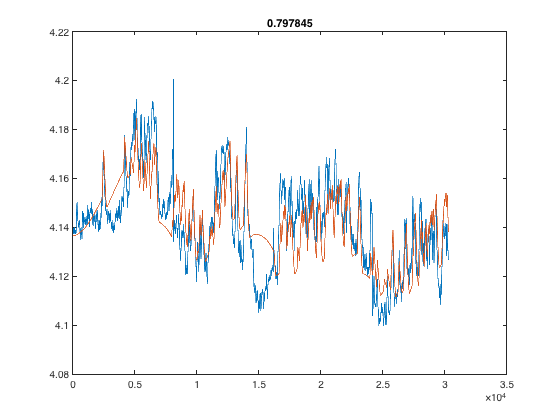

ignored_index = find(circadian_time_opt >= 10800 & circadian_time_opt< 10800+2700);
tau_pooled_opt = rawData_for_opt.tau_pooled;
tau_pooled_opt(ignored_index) = [];
% correlation = corr(tau_pooled,simulatedT_all)

figure
plot(tau_pooled_opt)
hold on
plot(simulatedT_all)
title(corr(tau_pooled_opt, simulatedT_all))


%if use the mean of asyPWP from optimization
% comment out the simulateBrainTemperature.m function line 95 mean_asyPWP = mean(asyPWP);
mean_asyPWP = 0.719094684370353

mean_asyPWP =    0.719094684370353



flagsWakeREM = states_pooled;
[simulatedT,asymptots] = simulateBrainTemperature (...
        flagsWakeREM, initial_temperature,circadian_time,1, SF, p.sizePWP, p.shiftPWP,...
        [p.lowerAsymptote, p.upperAsymptote, p.wakeTimeConstant, ...
         p.nremTimeConstant, p.scalePWP, p.circadianAmplitude, p.circadianPhase...
        ]);

mean_asyPWP =    0.719094684370353


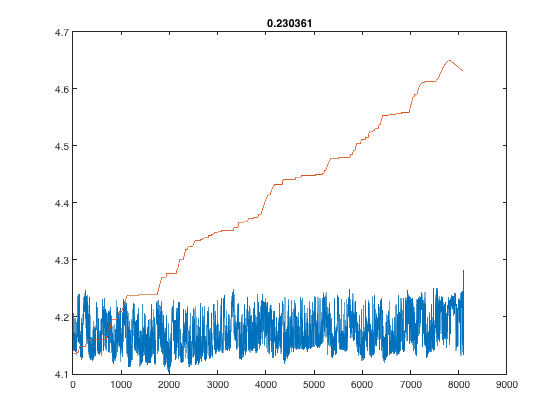

ignored_index = find(circadian_time >= 10800 & circadian_time< 10800+2700);
tau_pooled_plot = tau_pooled;
tau_pooled_plot(ignored_index) = [];

figure
plot(tau_pooled_plot)
hold on
plot(simulatedT)
title(corr(tau_pooled_plot, simulatedT))

% if use the corresponding mean of asyPWP:
% put back the the simulateBrainTemperature.m function line 95 mean_asyPWP = mean(asyPWP);

flagsWakeREM = states_pooled;
[simulatedT,asymptots] = simulateBrainTemperature (...
        flagsWakeREM, initial_temperature,circadian_time,1, SF, p.sizePWP, p.shiftPWP,...
        [p.lowerAsymptote, p.upperAsymptote, p.wakeTimeConstant, ...
         p.nremTimeConstant, p.scalePWP, p.circadianAmplitude, p.circadianPhase...
        ]);

mean_asyPWP =    2.097945816186561


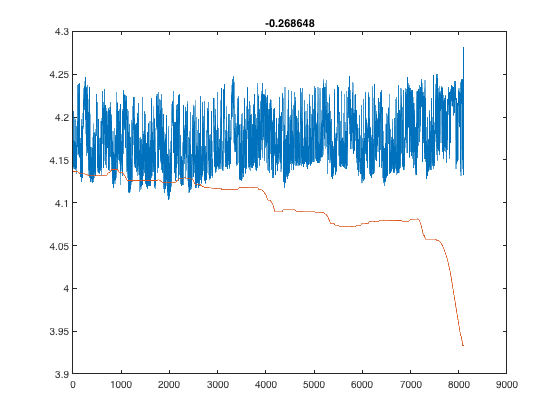

ignored_index = find(circadian_time >= 10800 & circadian_time< 10800+2700);
tau_pooled_plot = tau_pooled;
tau_pooled_plot(ignored_index) = [];

figure
plot(tau_pooled_plot)
hold on
plot(simulatedT)
title(corr(tau_pooled_plot, simulatedT))